## TSK Application on High Dimensionality Dataset

### Problem Description

In this project segment, we are working with a complex dataset called 'Epileptic Seizure Recognition'. The dataset consists of 11500 rows, each comprising of 178 EEG data points collected over 1 second, and a response variable y in column 179, the output. The response variable ranges from 1 to 5, indicating:

- Recording of seizure activity

- EEG recording was from the tumor area

- EEG recording was from healthy brain area, knowing the tumor area

- Eyes closed

- Eyes open

Subjects who are falling in the classes 2, 3, 4, 5 did not have an epileptic seizure.

Utilizing this dataset, we aim to classify any given EEG recording, into one of the 5 aforementioned states. Given its challenging nature though, training a model with 178 input features becomes a particularly complex task. To tackle this issue, we will be implementing feature selection and a parameter optimization algorithm to find an optimal tradeoff between performance and computational feasibility. 

### Finding the Optimal Parameters

According to instructions, we will be evaluating two parameters, and their effect on model performance. Specifically, the two parameters in question are: 

- Number of features

- Cluster radius

The algorithm that will select the optimal combination, will utilize grid search, among predetermined values for the number of features, and the length of the radius. For each combination, the best features, will be selected, according to the output of MRMR algorithm, and a k-fold cross validation will take place, for a more robust evaluation. This process, aims to create a robust and streamlined approach for parameter optimization for tackling high-dimensional classification challenges.

warning('off','all')
addpath("lib")
addpath("lib/datasets")
data_table = readtable("datasets/epileptic_seizure_data.csv", 'ReadVariableNames', false);
data_2 = table2array(data_table(:, 2:end));
[Dtrn_2, Dval_2, Dchk_2] = split_data(data_2);

Dimensions of Training Data:
        6900         179

Dimensions of Validation Data:
        2300         179

Dimensions of Checking Data:
        2300         179



We begin the optimization process, which will find the optimal parameters based on the overall accuracy (OA), performing 80 tests on combinations:

% Numbers of features and radii to search over
feature_numbers = [8, 10, 12, 14];
radius_a = [0.3, 0.5, 0.7, 0.9];

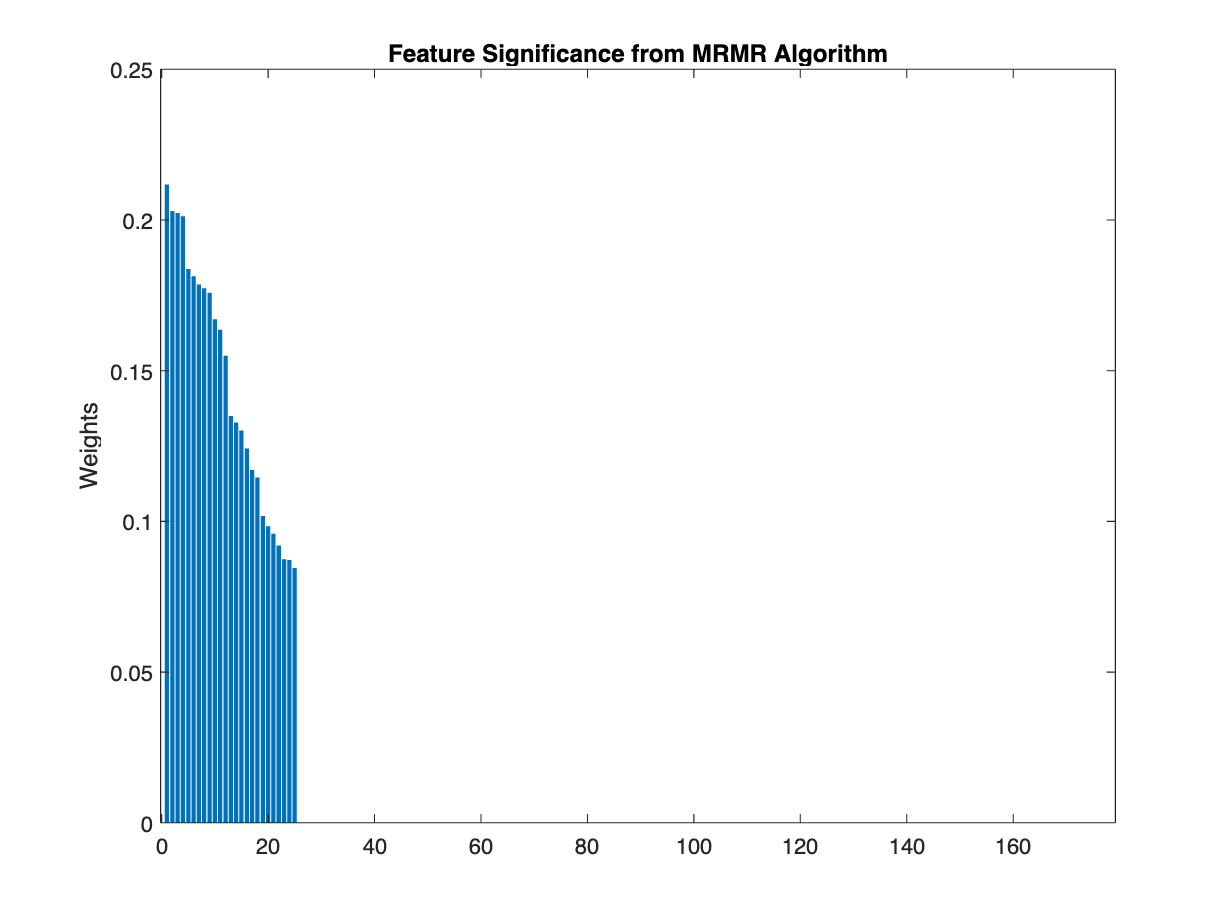

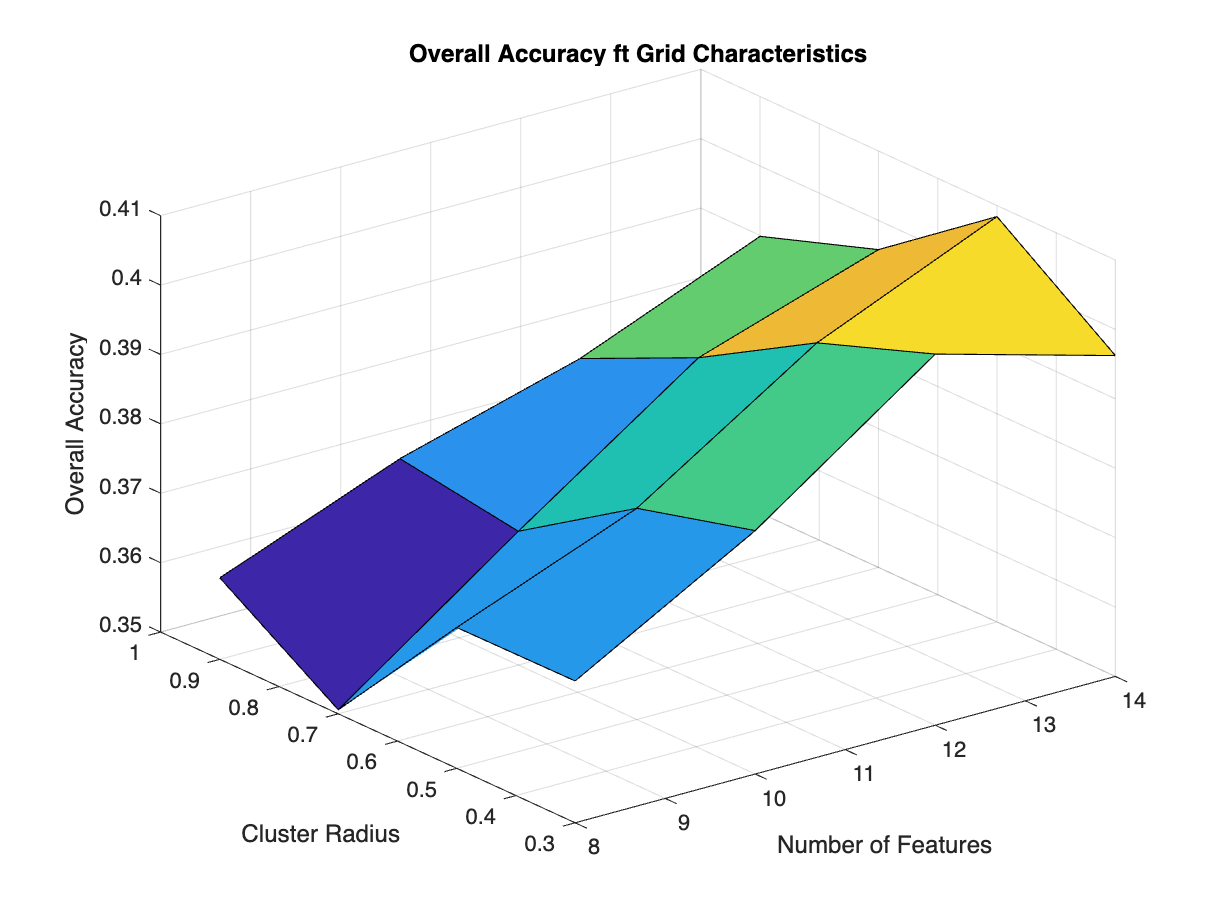

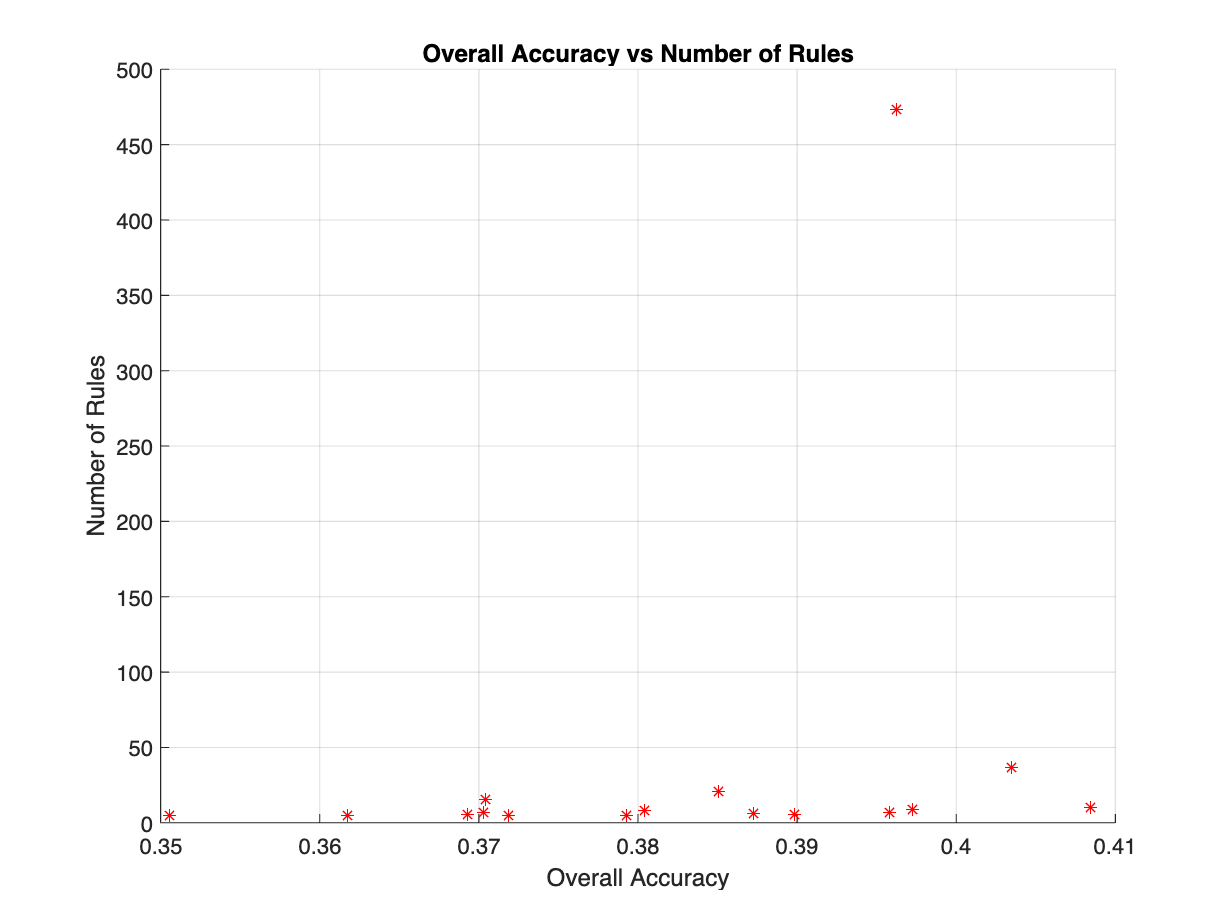

    Num_Features    Radius    Overall_Accuracy
    ____________    ______    ________________

          8          0.3          0.37043     
          8          0.5          0.37029     
          8          0.7          0.35058     
          8          0.9          0.36174     
         10          0.3          0.38507     
         10          0.5          0.38043     
         10          0.7          0.36928     
         10          0.9          0.37188     
         12          0.3          0.40348     
         12          0.5          0.39725     
         12          0.7          0.38725     
         12          0.9          0.37928     
         14          0.3          0.39623     
         14          0.5          0.40841     
         14          0.7           0.3958     
         14          0.9          0.38986     

    Num_Features    Radiu

tic;
[opt_feature_num, opt_radius, opt_feature_idxs, eval_metrics] = optimize_parameters(Dtrn_2, feature_numbers, radius_a);

time_param = toc;

### Training Optimal Model

As the process has now concluded, our optimal parameters are:

disp(table(opt_feature_num, opt_radius, 'VariableNames', {'Optimal Number of Features', 'Optimal Radius'}));

    Optimal Number of Features    Optimal Radius
    __________________________    ______________

                14                     0.5      



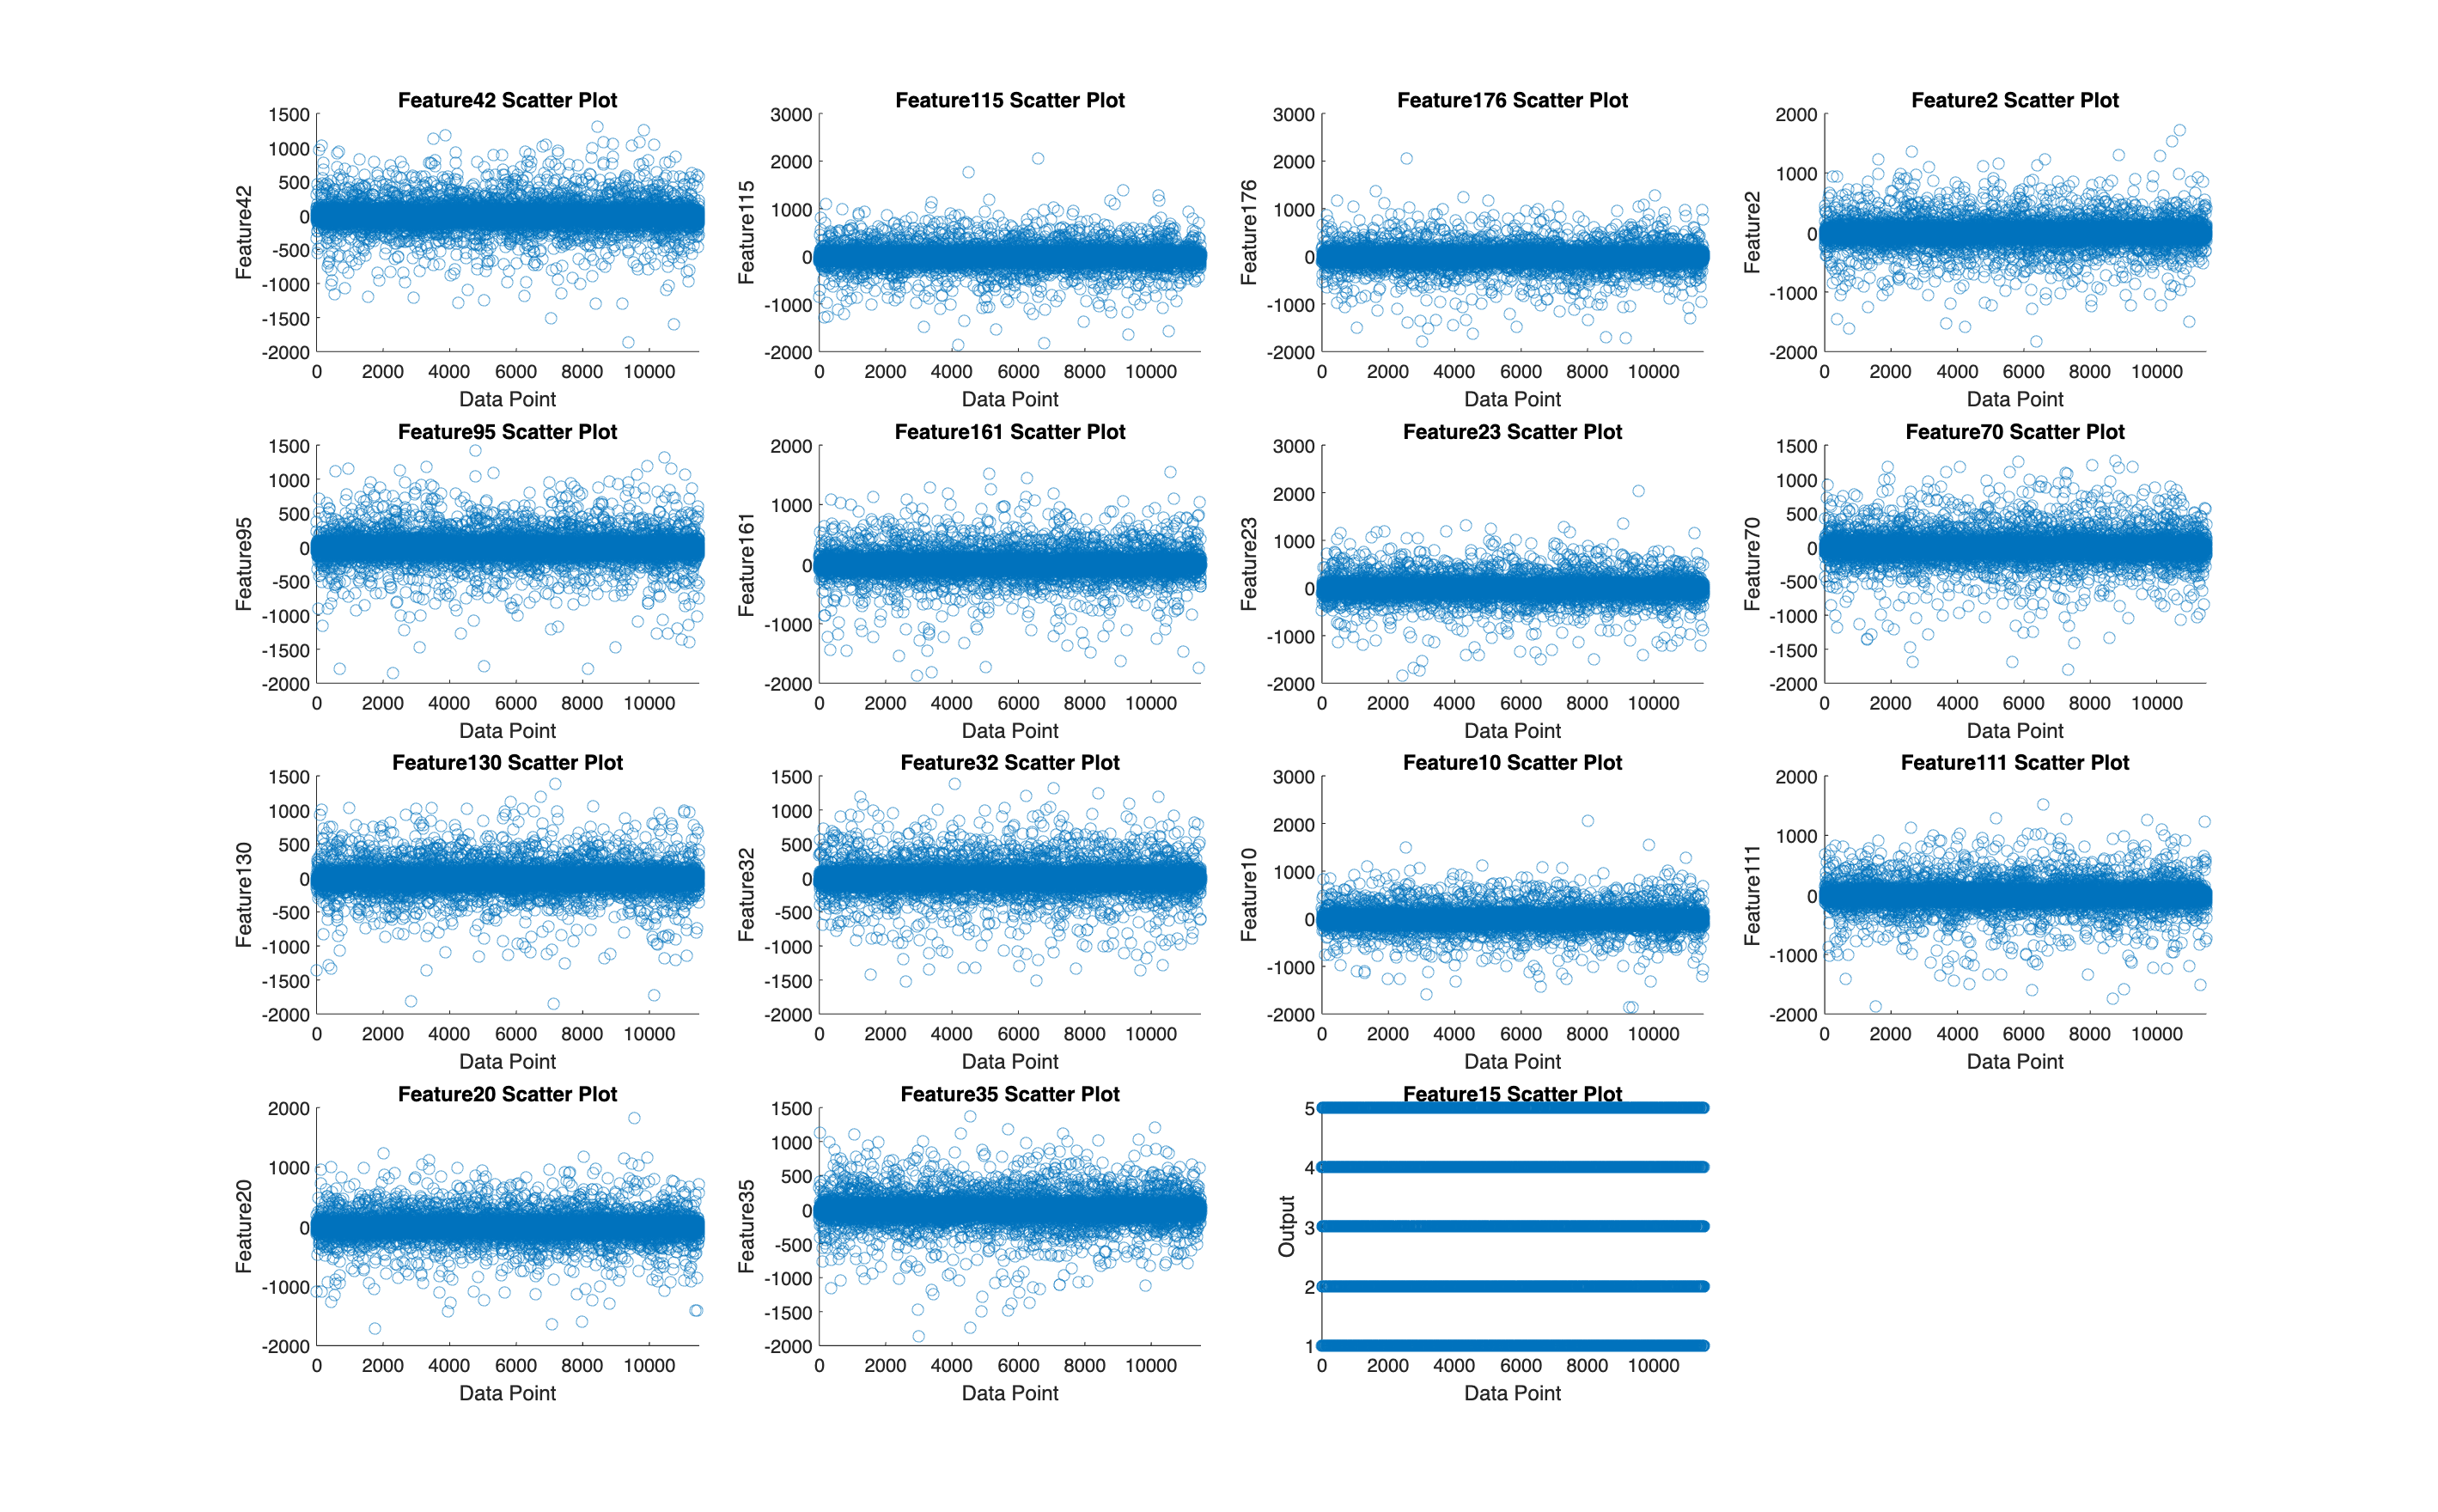

% Visualize the selected features and the output
visualize_data(data_2, [], opt_feature_idxs);

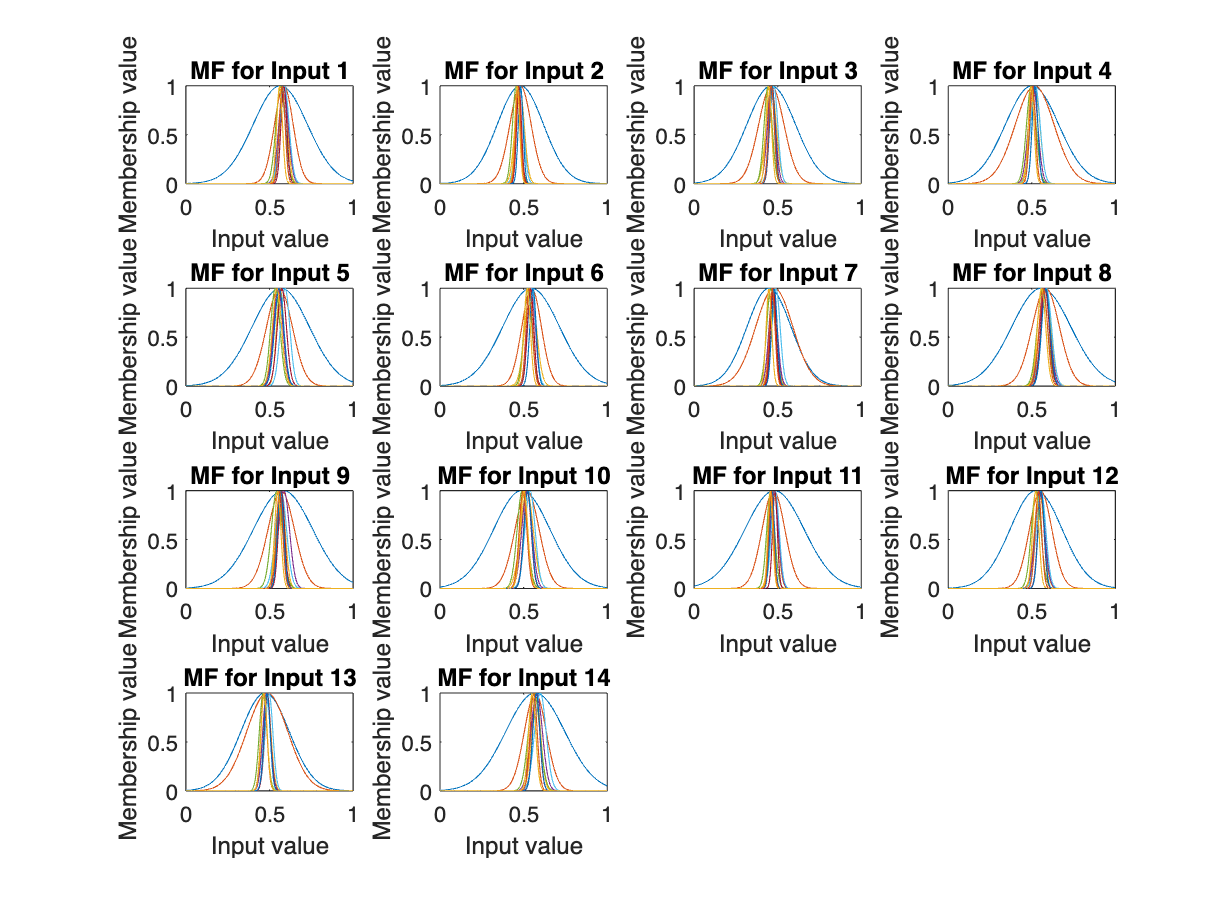

% Update the sets to proceed with our model training
Dtrn_opt = [Dtrn_2(:, opt_feature_idxs) Dtrn_2(:, end)];
Dval_opt = [Dval_2(:, opt_feature_idxs) Dval_2(:, end)];
Dchk_opt = [Dchk_2(:, opt_feature_idxs) Dchk_2(:, end)];

% Initialize Optimal Model
opt_model = struct('Type', 'Dependent', 'Radius', opt_radius, 'Part', 2);
initial_opt_fis = initialize_tsk_model(Dtrn_opt, opt_model);
plot_mf(initial_opt_fis, opt_feature_num);

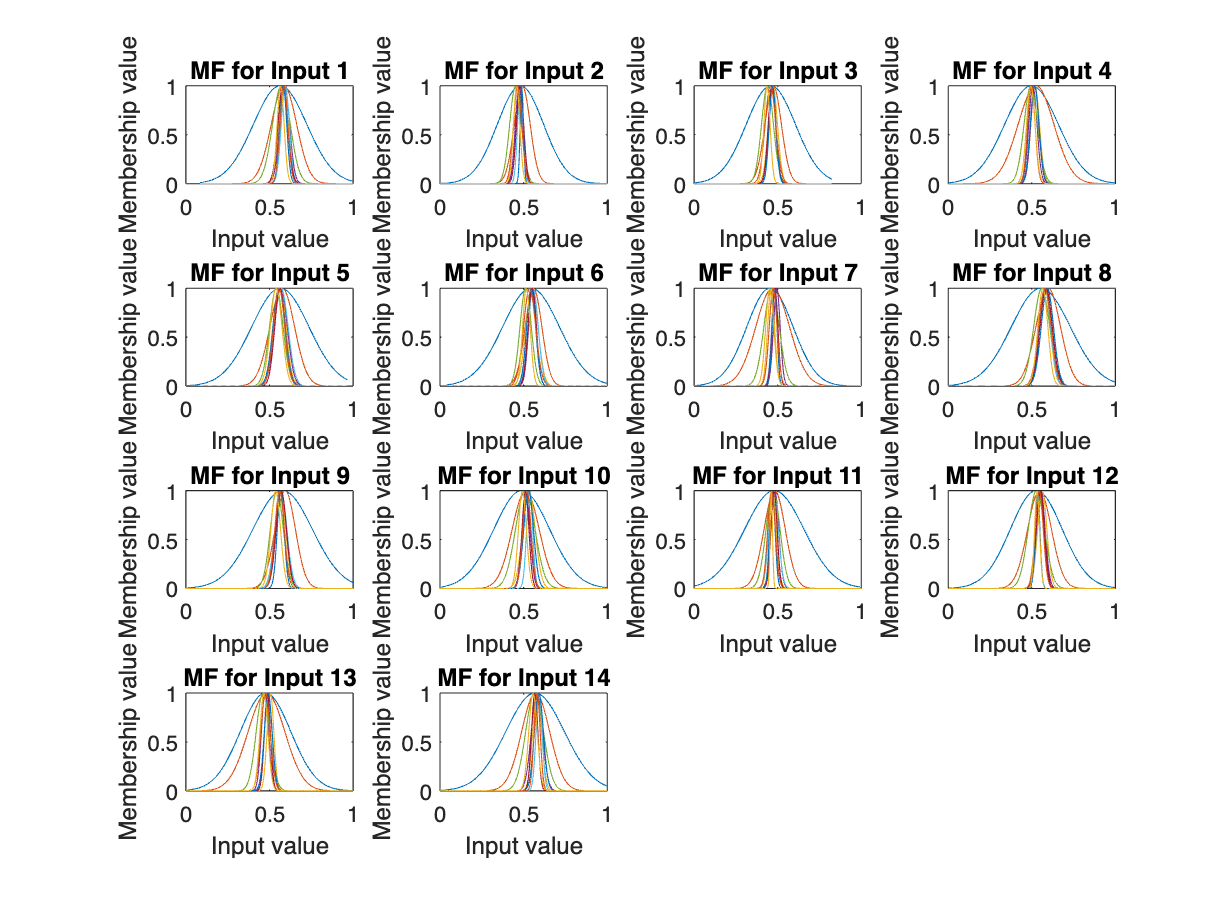

% Train Optimal Model
tic;
[trained_opt_fis, training_info_opt] = train_tsk_model(initial_opt_fis, Dtrn_opt, Dval_opt, 200);
time_opt = toc;
plot_mf(trained_opt_fis, opt_feature_num);

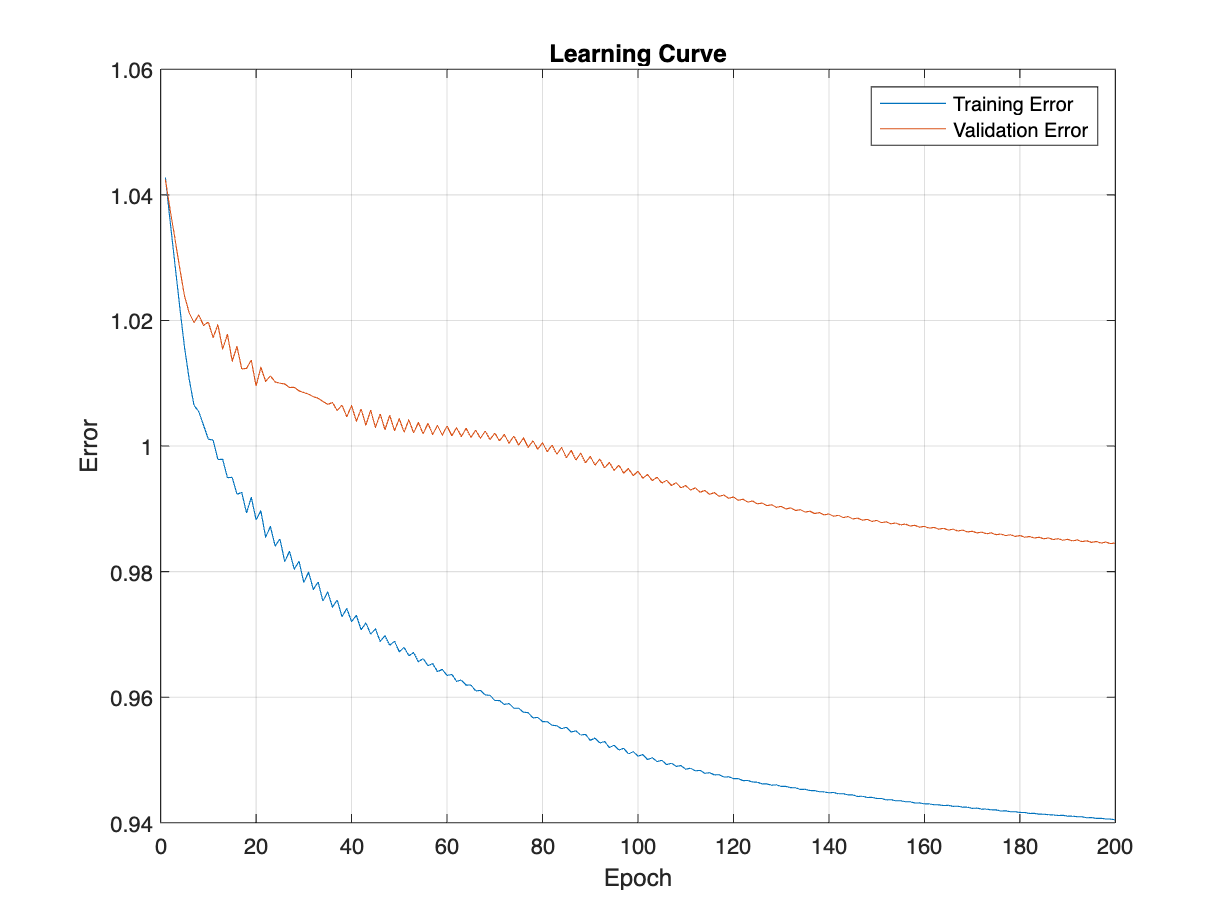

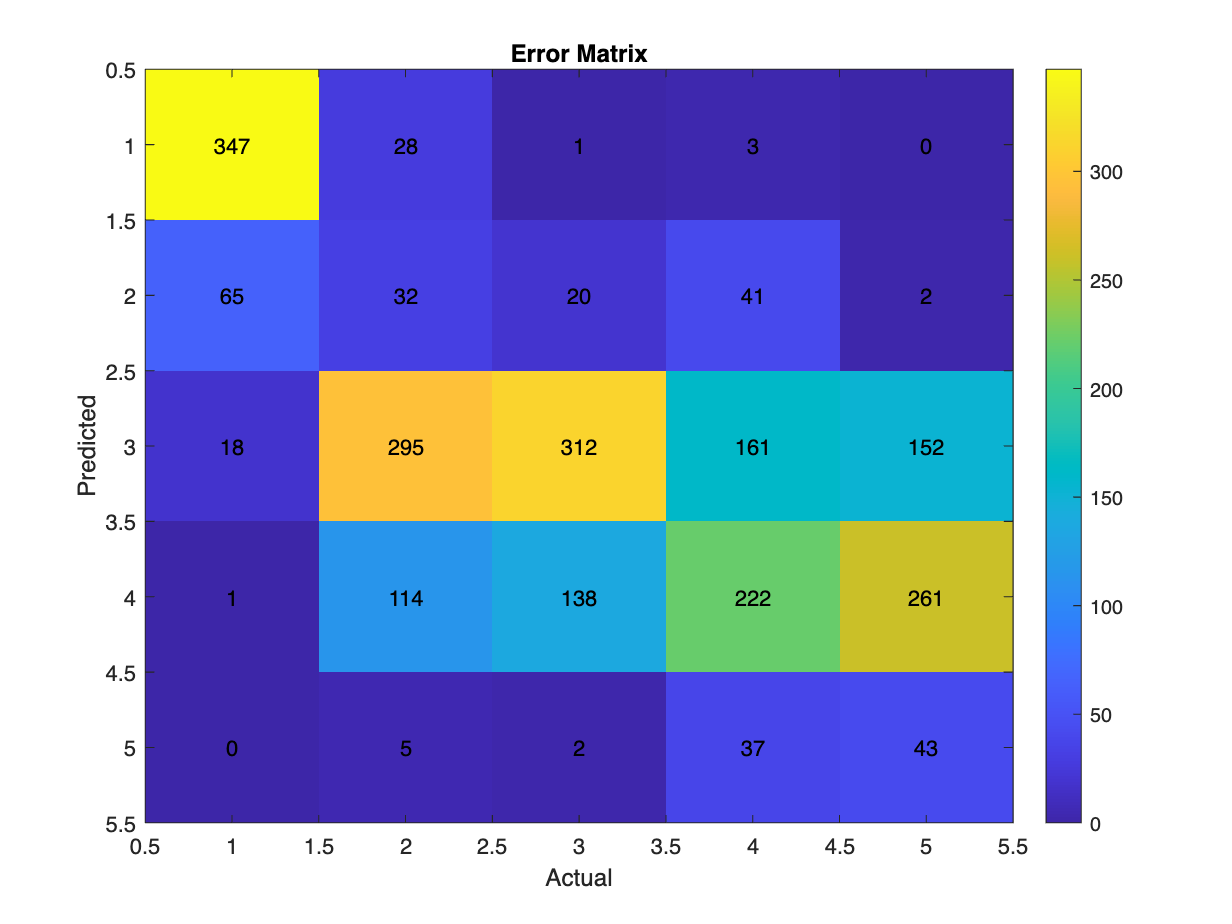

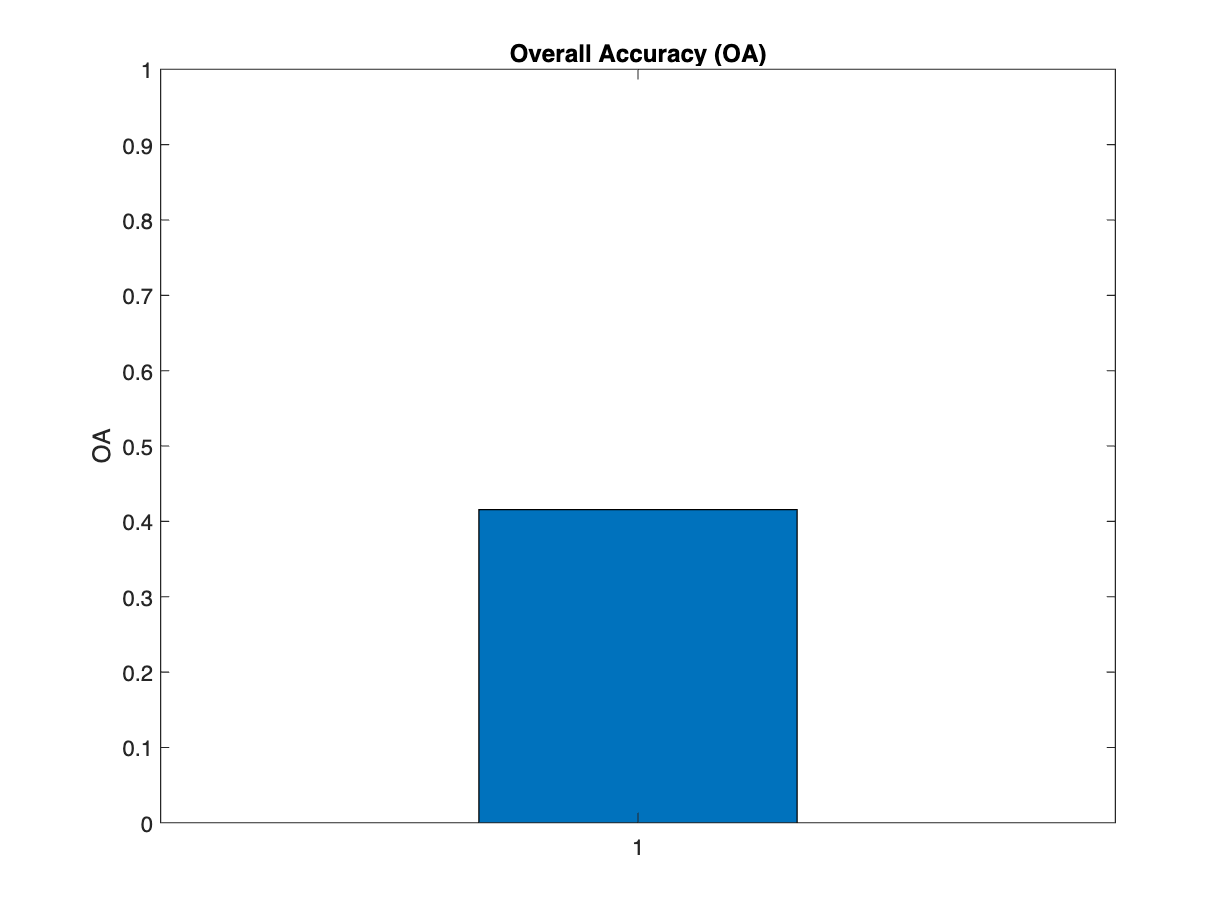

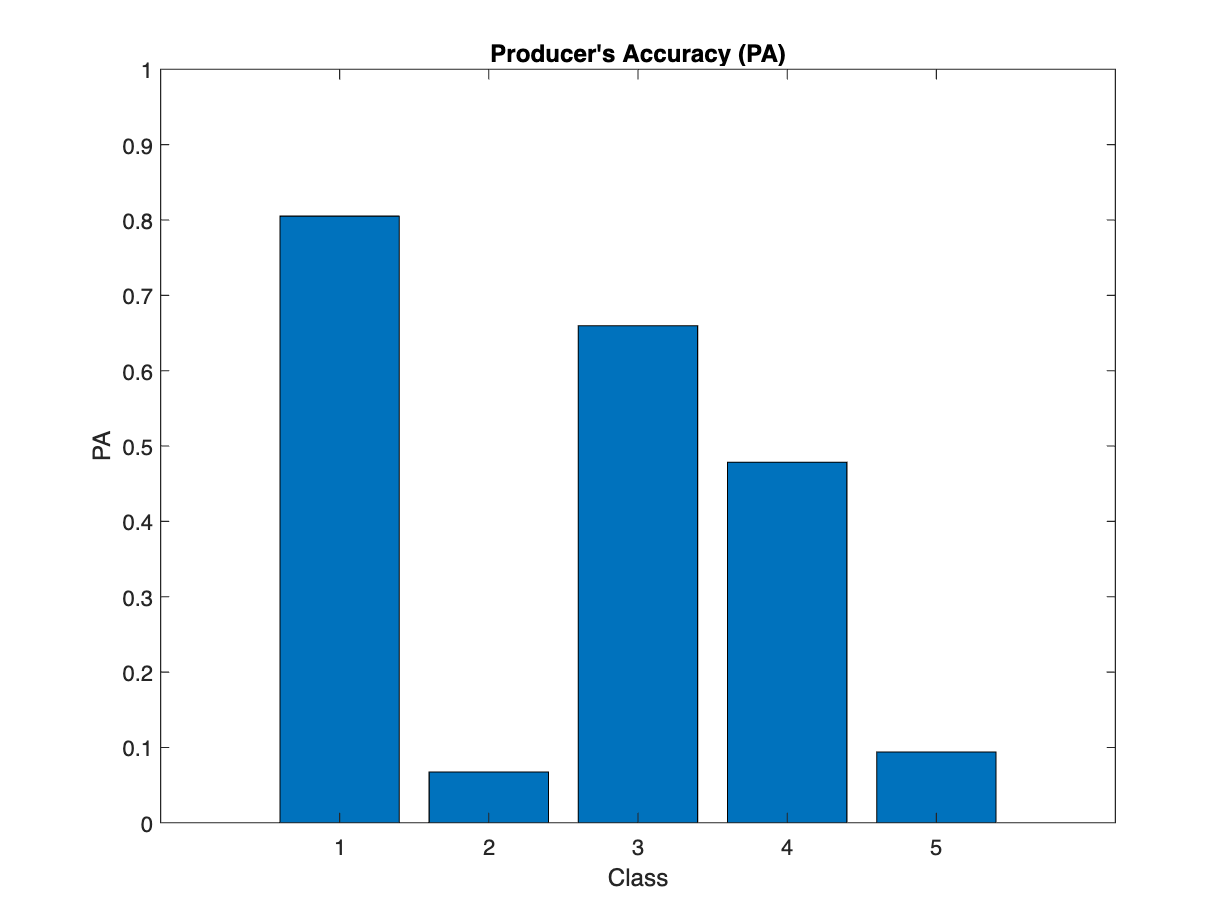

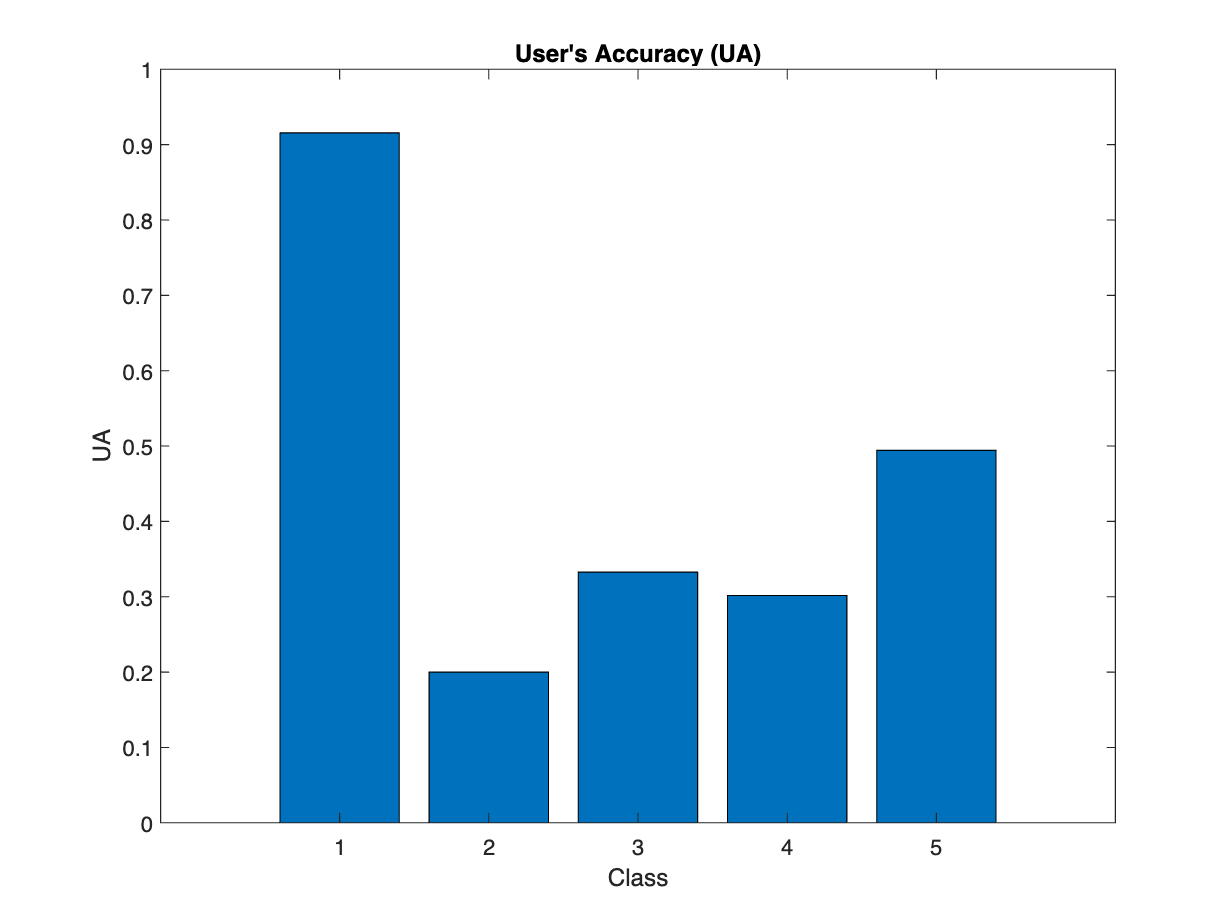

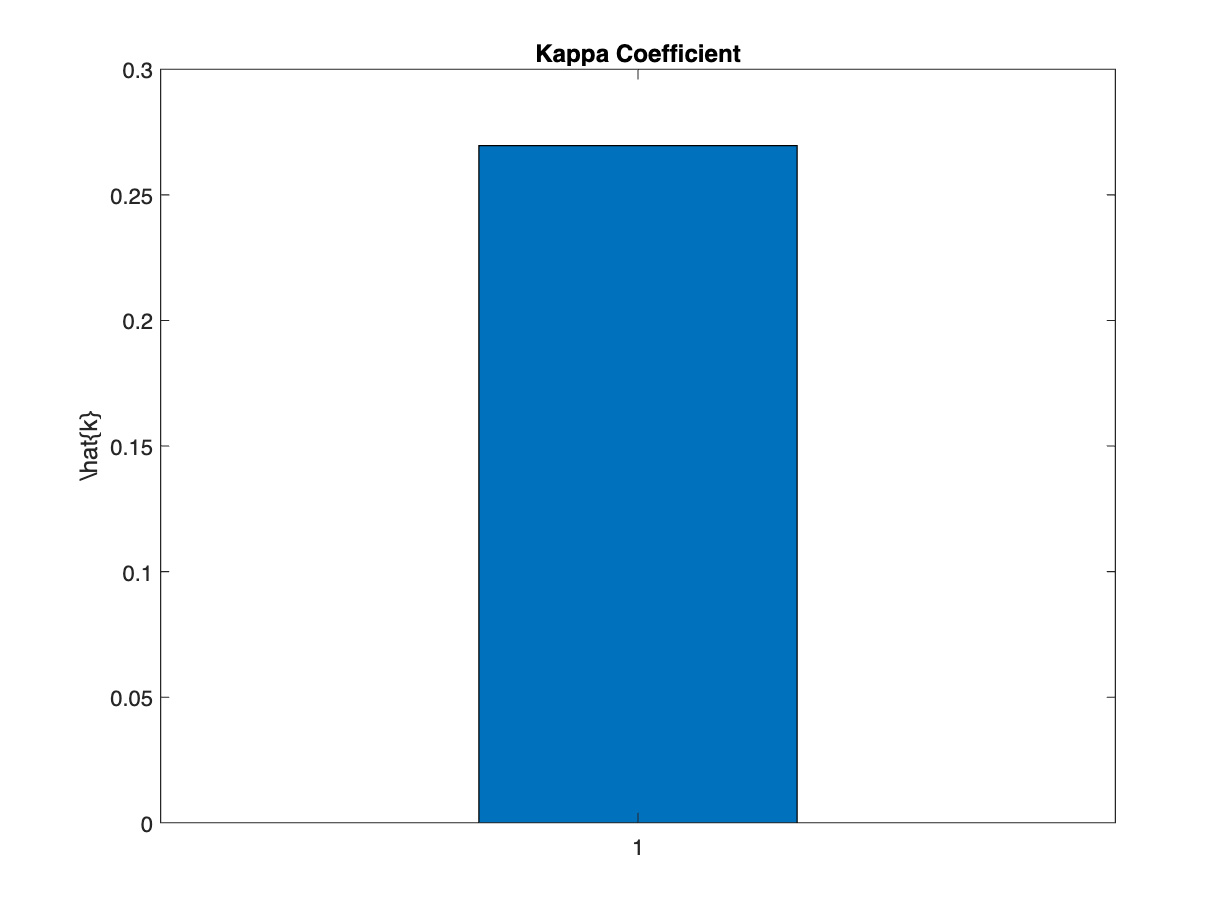

[error_matrix_opt, OA_opt, PA_opt, UA_opt, kappa_opt] = metrics_evaluation(trained_opt_fis, Dchk_opt, 5);
plot_metrics(error_matrix_opt, OA_opt, PA_opt, UA_opt, kappa_opt, training_info_opt.trainError, training_info_opt.chkError);

% Create table for OA and Kappa
table_OA_Kappa = table(OA_opt, kappa_opt, 'VariableNames', {'OA', 'Kappa'});
disp(table_OA_Kappa);

      OA        Kappa 
    _______    _______

    0.41565    0.26962



% Create table for PA
classLabels_PA = strcat('PA_Class_', arrayfun(@num2str, 1:5, 'UniformOutput', false));
table_PA = array2table(PA_opt, 'VariableNames', classLabels_PA);
disp(table_PA);

    PA_Class_1    PA_Class_2    PA_Class_3    PA_Class_4    PA_Class_5
    __________    __________    __________    __________    __________

      0.8051       0.067511      0.65962       0.47845       0.093886 



% Create table for UA
classLabels_UA = strcat('UA_Class_', arrayfun(@num2str, 1:5, 'UniformOutput', false));
table_UA = array2table(UA_opt, 'VariableNames', classLabels_UA);
disp(table_UA);

    UA_Class_1    UA_Class_2    UA_Class_3    UA_Class_4    UA_Class_5
    __________    __________    __________    __________    __________

     0.91557         0.2         0.33262       0.30163       0.49425  



### Comments and Results

The optimized model, was achieved through an extensive parameter tuning and feature selection process. Utilizing the MRMR algorithm to select the most important features whilst trying to mitigate feature correlation, along with the grid search and 5 fold cross validation, offered a robust process for optimizing the model's parameters. Given the high-dimensionality of our dataset, which consists of 178 features, this optimization was a crucial step towards model training. As seen below, the optimization process took over an hour, and as we see from the 'Overall Accuracy vs Number of Rules' figure, at one point, a combination reached close to 500 rules. Given the fact that the highest number of features tested in a model was 14, less than 10% of the available features, we can understand the significance of this process.

disp(table(time_param, time_opt, 'VariableNames', {'Parameter Optimization Time', 'Model Training Time'}));

    Parameter Optimization Time    Model Training Time
    ___________________________    ___________________

              4774.4                     66.855       



Our model, characterized by 14 features and a radius of 0.5, seems suboptimal overall. The optimization process clearly indicated that more features offer better accuracy. Testing more cases, with a small radius (less than 0.4) proved to be computationally intensive. Regardless of the Overall_Accuracy, our model seems to be performing well in identifying class 1, meaning that it is able to understand whether a patient is having a seizure.

The radius parameter directly influenced the fuzzy set overlap in the input variable space. In our optimal model with 14 features and a radius of 0.5, the fuzzy sets showed moderate overlap, which contributed to activating only 10 rules.

The partitioning of the input space and the number of active rules are not directly proportional. Our observations emphasize the significance of optimizing the radius and number of features to achieve a balanced model.

Below we can see the rules of our model. As seen from the optimization process, a close second in performance (OA) was a model consisting of 14 features, but with a smaller radius of 0.3, which produced 473 rules. So we can attest, that more rules do not necessarily mean a better performance. 

disp(trained_opt_fis.Rules);

`1×10 `[`fisrule`](matlab:helpPopup fisrule)` array with properties:`

`Description`

`Antecedent`

`Consequent`

`Weight`

`Connection`

`Details:                                                                                                  `

`Description`                                                                                         

    `1 ``    "in1==mf1 & in2==mf1 & in3==mf1 & in4==mf1 & in5==mf1 & in6==mf1 & in7==mf1 & in8==mf1 & in9==mf1 & in10==mf1 & in11==mf1 & in12==mf1 & in13==mf1 & in14==mf1 => out1=mf1 (1)"               `

    `2 ``    "in1==mf2 & in2==mf2 & in3==mf2 & in4==mf2 & in5==mf2 & in6==mf2 & in7==mf2 & in8==mf2 & in9==mf2 & in10==mf2 & in11==mf2 & in12==mf2 & in13==mf2 & in14==mf2 => out1=mf2 (1)"               `

    `3 ``    "in1==mf3 & in2==mf3 & in3==mf3 & in4==mf3 & in5==mf3 & in6==mf3 & in7==mf3 & in8==mf3 & in9==mf3 & in10==mf3 & in11==mf3 & in12==mf3 & in13==mf3 & in14==mf3 => out1=mf3 (1)"               `

    `4 ``    "in1==mf4 & in2==mf4 & in3==mf4 & in4==mf4 & in5==mf4 & in6==mf4 & in7==mf4 & in8==mf4 & in9==mf4 & in10==mf4 & in11==mf4 & in12==mf4 & in13==mf4 & in14==mf4 => out1=mf4 (1)"               `

    `5 ``    "in1==mf5 & in2==mf5 & in3==mf5 & in4==mf5 & in5==mf5 & in6==mf5 & in7==mf5 & in8==mf5 & in9==mf5 & in10==mf5 & in11==mf5 & in12==mf5 & in13==mf5 & in14==mf5 => out1=mf5 (1)"               `

    `6 ``    "in1==mf6 & in2==mf6 & in3==mf6 & in4==mf6 & in5==mf6 & in6==mf6 & in7==mf6 & in8==mf6 & in9==mf6 & in10==mf6 & in11==mf6 & in12==mf6 & in13==mf6 & in14==mf6 => out1=mf6 (1)"               `

    `7 ``    "in1==mf7 & in2==mf7 & in3==mf7 & in4==mf7 & in5==mf7 & in6==mf7 & in7==mf7 & in8==mf7 & in9==mf7 & in10==mf7 & in11==mf7 & in12==mf7 & in13==mf7 & in14==mf7 => out1=mf7 (1)"               `

    `8 ``    "in1==mf8 & in2==mf8 & in3==mf8 & in4==mf8 & in5==mf8 & in6==mf8 & in7==mf8 & in8==mf8 & in9==mf8 & in10==mf8 & in11==mf8 & in12==mf8 & in13==mf8 & in14==mf8 => out1=mf8 (1)"               `

    `9 ``    "in1==mf9 & in2==mf9 & in3==mf9 & in4==mf9 & in5==mf9 & in6==mf9 & in7==mf9 & in8==mf9 & in9==mf9 & in10==mf9 & in11==mf9 & in12==mf9 & in13==mf9 & in14==mf9 => out1=mf9 (1)"               `

    `10``    "in1==mf10 & in2==mf10 & in3==mf10 & in4==mf10 & in5==mf10 & in6==mf10 & in7==mf10 & in8==mf10 & in9==mf10 & in10==mf10 & in11==mf10 & in12==mf10 & in13==mf10 & in14==mf10 => out1=mf10 (1)"`